pcdDir = "/Volumes/Expansion/Calibration/ecal_meas/2023-02-04_15-20-34.496_wildpose_v1.1/lidar/";
pcdFileNames = [
"livox_frame_1675516837_561540720.pcd"
"livox_frame_1675516837_661535984.pcd"
"livox_frame_1675516837_761489168.pcd"
"livox_frame_1675516837_861364272.pcd"
"livox_frame_1675516837_961395824.pcd"
"livox_frame_1675516838_061330928.pcd"
"livox_frame_1675516838_161624400.pcd"
"livox_frame_1675516838_261372624.pcd"
"livox_frame_1675516838_361432080.pcd"
"livox_frame_1675516838_461377712.pcd"
]

pcdFileNames = 10×1 string array
    "livox_frame_1675516837_561540720.pcd"
    "livox_frame_1675516837_661535984.pcd"
    "livox_frame_1675516837_761489168.pcd"
    "livox_frame_1675516837_861364272.pcd"
    "livox_frame_1675516837_961395824.pcd"
    "livox_frame_1675516838_061330928.pcd"
    "livox_frame_1675516838_161624400.pcd"
    "livox_frame_1675516838_261372624.pcd"
    "livox_frame_1675516838_361432080.pcd"
    "livox_frame_1675516838_461377712.pcd"


## Merge

% Initialize ptCloud using the first file
filepath = fullfile(pcdDir, pcdFileNames(1));
ptCloud = pcread(filepath);

% Load and merge the next set of point clouds
for i = 2:length(pcdFileNames)
    filepath = fullfile(pcdDir, pcdFileNames(i));
    tmpPtCloud = pcread(filepath);
    ptCloud = pcmerge(ptCloud, tmpPtCloud, 0.001); % Using a merge tolerance of 0.001, adjust accordingly
end

pcwrite( ...
    ptCloud, ...
    fullfile( ...
        "/Users/ikuta/Documents/Projects/wildpose-applications/results/", ...
        "merge_04.pcd" ...
   ) ...
)

## Visualization

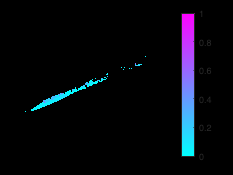

pcshow(ptCloud.Location, ptCloud.Intensity / max(ptCloud.Intensity))
title(filepath, 'Interpreter','none')
xlabel("X")
ylabel("Y")
zlabel("Z")
colorbar
colormap("cool")